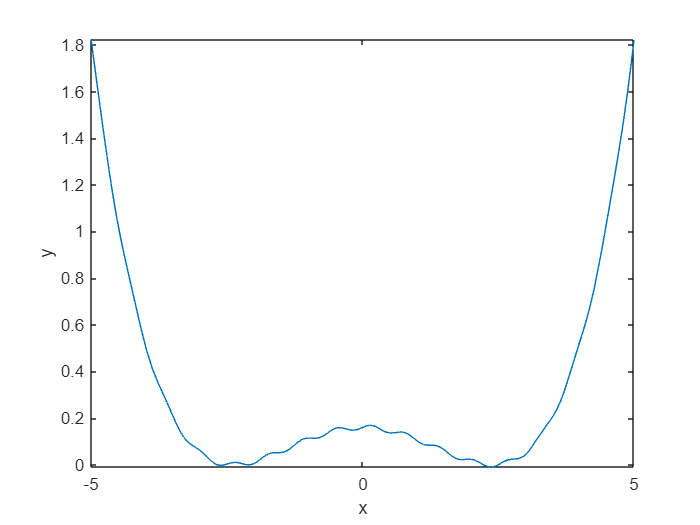

f = @(x) 0.01*sin(10*x)+(0.07*x.^2-0.4).^2;

fplot(f);
xlabel('x');
ylabel('y');


x0 = -0.5;
x1 = x0 + 0.1;
alfa = 1.5;

[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =    -0.4000    0.9000


iteracje = 1

alfa = 2;

[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =    -0.4000    1.6000


iteracje = 1

x0 = 32;
x1 = x0 + 0.1;
alfa = 1.5;

[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0


alfa = 2;

[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0

4. Wyznaczyć przedział minimum funkcji metodą **ekspansji, następnie zawęzić przedział metodą kontrakcji** (uzupełnienie ekspansji)

5. Podać ilość kroków do osiągnięcia rozwiązań.

6. Przeanalizować warunek stopu, wnioski.

x0 = -0.5;
x1 = x0 + 0.1;
alfa = 2;
beta = 0.5;

[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =    -0.4000    1.6000


iteracje = 1

[minimum_cont, iteracje] = contract(f, minimum(1), minimum(2), beta, 10000)

minimum_cont = "no_improv"

iteracje = 10000


x0 = 32;
x1 = x0 + 0.1;
[minimum, iteracje] = expanse(f, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0

[minimum_cont, iteracje] = contract(f, minimum(1), minimum(2), beta, 10000)

minimum_cont =   -32.1000   32.1000


iteracje = 2

Druga funkcja

px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5;
W = polyfit(px, py, stopien);

fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x

fx = function_handle with value:
    @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x


fplot(fx);

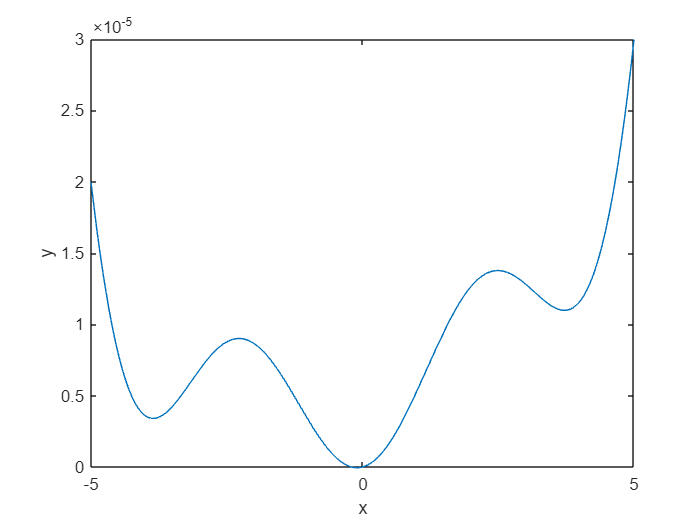

xlabel('x');
ylabel('y');


x0 = -0.5;
x1 = x0 + 0.1;
alfa = 1.5;

[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =    -3.0375   -1.3500


iteracje = 4

alfa = 2;

[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =    -3.2000         0


iteracje = 2

x0 = 32;
x1 = x0 + 0.1;
alfa = 2;

[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0

alfa = 2;

[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0

Punkty 4,5,6

x0 = -0.5;
x1 = x0 + 0.1;
alfa = 1.5;
beta = 0.5;

[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =    -3.0375   -1.3500


iteracje = 4

[minimum_cont, iteracje] = contract(fx, minimum(1), minimum(2), beta, 10000)

minimum_cont = "no_improv"

iteracje = 10000

x0 = 32;
x1 = x0 + 0.1;
[minimum, iteracje] = expanse(fx, x0, x1, alfa, 100)

minimum =   -32.1000   32.1000


iteracje = 0

[minimum_cont, iteracje] = contract(fx, minimum(1), minimum(2), beta, 10000)

minimum_cont =   -32.1000   32.1000


iteracje = 2

minimum=[-28.4,-24.4];
beta=0.9;

[minimum_cont, iteracje] = contract(fx, minimum(1), minimum(2), beta, 10000)

minimum_cont =   -28.4000  -24.4000


iteracje = 2